clear
num_s = [0.0625];
den_s = [1, 0, 0.25];
Ts = 1; 
sys_z = c2d(tf(num_s, den_s), Ts, 'zoh')


sys_z =
 
  0.0306 z + 0.0306
  -----------------
  z^2 - 1.755 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


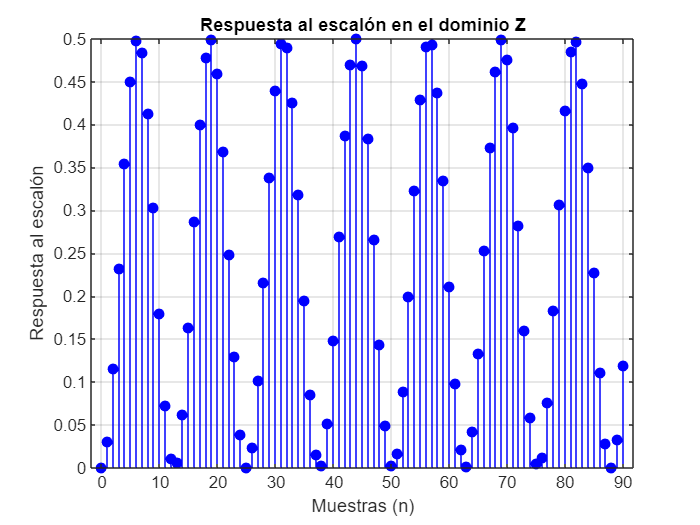

n = 0:1:90;
[y, n] = step(sys_z, n);
stem(n, y, 'b', 'filled');
xlabel('Muestras (n)');
ylabel('Respuesta al escalón');
title('Respuesta al escalón en el dominio Z');
grid on;